% Filtro IIR Butterworth - Pasa bajo - FPGA
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b21b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - IIR - Diseño del filtro Pasa Bajos**

**Parámetros de diseño**

fm=150000;             % Hz,  Frecuencia de Muestreo
fMAX=fm/2;
                         fc=6380;
fp=1000 ;                  fs=9500 ;              
Ap=0.5 ;                   As=10 ;                          

**Diseño del filtro**

- Transformar las caracteristicas de frecuencia de paso bajo a paso bajo normalizado

Fc=fc/fc;
Fs=fs/fc;
Fp=fp/fc;

- Orden del filtro:

N=mi_butter_orden_lp(Fp, Ap, Fs, As)

N =      3


- Función de transferencia y respuesta en frecuencia

[BS, AS]=mi_butter(N);
sysS=tf(BS,AS)

sysS =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



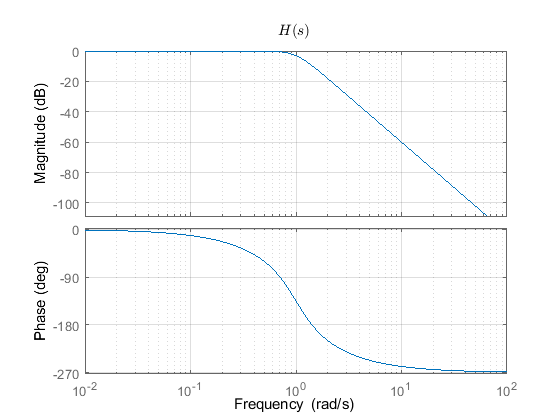

fig0=figure; bode(sysS); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;...
saveas(fig0,'output/fpga_iir_lp_butterworth_0','jpg');

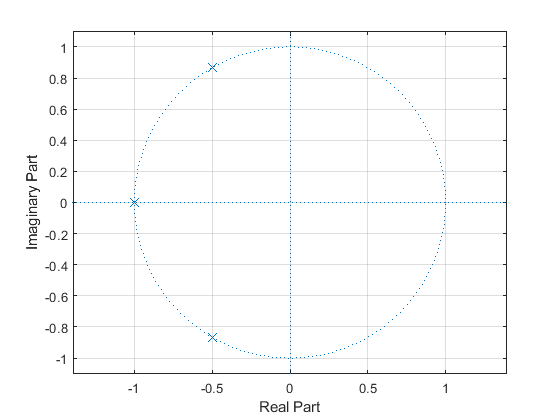


fig1=figure; Np=max(length(BS),length(AS));
zplane( [zeros(1, Np-length(BS)) BS], [  zeros(1, Np-length(AS)) AS] );...
grid on; saveas(fig1,'output/fpga_iir_lp_butterworth_1','jpg');


syms s; ecu_latex = ['H(s)=', latex(poly2sym(BS,s)/poly2sym(AS,s))];
save_ecu('output/fpga_iir_lp_butterworth_ecu_SM.tex', ecu_latex);

- Transformación en frecuencia

[Bs, As] = mi_lp2lp(BS, AS, 2*pi*fc);
syss=tf(Bs,As)

syss =
 
                       1.133e27
  --------------------------------------------------
  1.759e13 s^3 + 1.41e18 s^2 + 5.654e22 s + 1.133e27
 
Continuous-time transfer function.



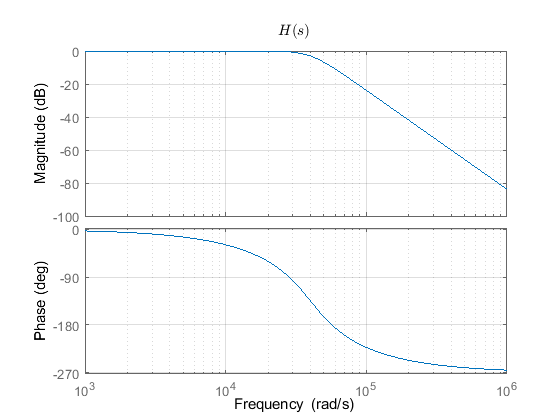

fig2=figure; bode(syss); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;   ...
saveas(fig2,'output/fpga_iir_lp_butterworth_2','jpg');

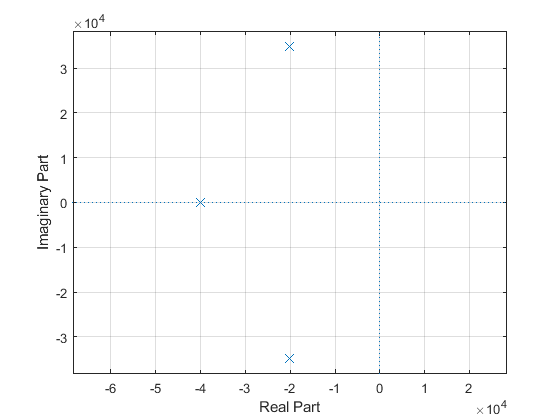


fig3=figure; Np=max(length(Bs),length(As));
zplane( [zeros(1, Np- length(Bs)) Bs  ], [zeros(1, Np- length(As))  As ] ); ...
grid on; saveas(fig3,'output/fpga_iir_lp_butterworth_3','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(Bs,s)/poly2sym(As,s))];
save_ecu('output/fpga_iir_lp_butterworth_ecu_s.tex', ecu_latex);

**Transformación bilinear - matlab.**

mapeo="bilineal(matlab)";

switch mapeo
    case "integración"
        [Bz, Az]=mi_integral(Bs, As, fm);
    case "invariante al impulso"
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case "invariante(matlab)"
        [Bz, Az]=impinvar(Bs, As, fm);
    case "bilineal"
        [Bz, Az]=mi_bilinear(Bs, As, fm, fs);
    case "bilineal(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm);     
    case "bilineal-prewarping(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm, fc); 
end
m=max( abs([ Bz, Az ]) ); Bz=Bz/m; Az=Az/m;
Bz=Bz/Az(1); Az=Az/Az(1);
sysz=tf(Bz,Az,1/fm,'Variable','z^-1')

sysz =
 
  0.001828 + 0.005483 z^-1 + 0.005483 z^-2 + 0.001828 z^-3
  --------------------------------------------------------
          1 - 2.47 z^-1 + 2.072 z^-2 - 0.5869 z^-3
 
Sample time: 6.6667e-06 seconds
Discrete-time transfer function.



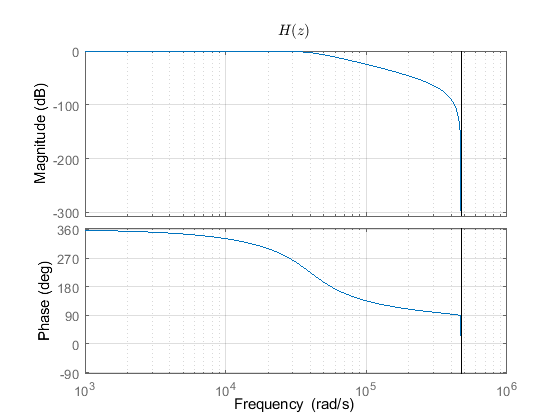

syms z; fig4=figure; bode(sysz); grid on;...
title(sprintf('$$%s$$', 'H(z)'), 'Interpreter','latex');    ...
saveas(fig4, 'output/fpga_iir_lp_butterworth_4', 'jpg');

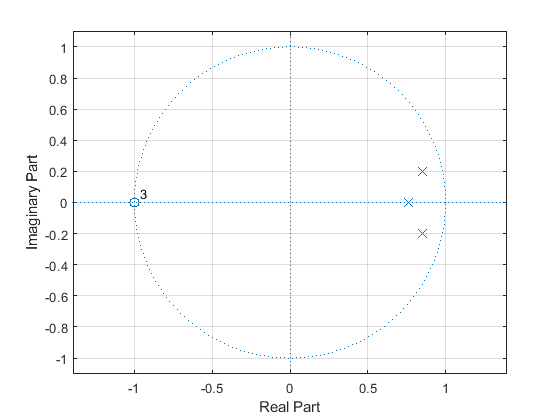


fig5=figure; Np=max( length(Bz),length(Az) );
zplane( [  zeros(1, Np- length(Bz)) Bz], [ zeros(1, Np- length(Az)) Az ] );...
grid on; saveas(fig5,'output/fpga_iir_lp_butterworth_5','jpg');

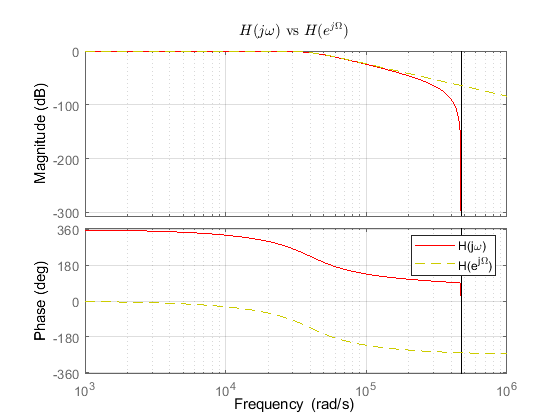


fig6=figure; bode(sysz,'r',syss,'y--'); grid on;...
title(sprintf('$$%s$$', 'H(j\omega)\mbox{ vs }H(e^{j\Omega})'), 'Interpreter','latex');    ...    
legend( sprintf('%s', 'H(j\omega)'), sprintf('%s', 'H(e^{j\Omega})'));    
saveas(fig6,'output/fpga_iir_lp_butterworth_6','jpg');

syms z; ecu_latex = ['H(z)=', latex(poly2sym(Bz,z)/poly2sym(Az,z))];
save_ecu('output/fpga_iir_lp_butterworth_ecu_z.tex', ecu_latex);

**Generación de la linea para la fpga**

Nbits=64;
Qbits=32;
fpga_coef=to_fpga(Bz, Az, N, fm, Qbits,Nbits, 'IIR - Pasa Bajo', mapeo)

fpga_coef =     '//Filtro IIR - Pasa Bajo - bilineal(matlab)
     //Orden: 3
     //Frecuencia de Muestreo: 150000 (Hz)
     assign dx0=64'0x000000000077C7B3;assign dx1=64'0x0000000001675719;assign dx2=64'0x0000000001675719;assign dx3=64'0x000000000077C7B3; 
     			
     assign dy1=64'0x00000002785B8840;assign dy2=64'0xFFFFFFFDEDA83EAA;assign dy3=64'0x00000000963DFB80; 
     			'


saveImplementacion('output/fpga_iir_lp_butterworth_fpga_coef.txt', fpga_coef); ...
fprintf('%s\n',fpga_coef) 

//Filtro IIR - Pasa Bajo - bilineal(matlab)
//Orden: 3
//Frecuencia de Muestreo: 150000 (Hz)
assign dx0=64'0x000000000077C7B3;assign dx1=64'0x0000000001675719;assign dx2=64'0x0000000001675719;assign dx3=64'0x000000000077C7B3; 
			
assign dy1=64'0x00000002785B8840;assign dy2=64'0xFFFFFFFDEDA83EAA;assign dy3=64'0x00000000963DFB80; 
			


**Generación de la linea para inicializar el callback de simulink**

PRECISION_STM32=8;
simulink_coef=to_simulink(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Butterworth - Pasa Bajo', mapeo); ...
saveImplementacion('output/stm32_iir_lp_butterworth_simulink_coef.txt', simulink_coef); ...
fprintf('%s\n', simulink_coef) 

	%Filtro IIR - Butterworth - Pasa Bajo - bilineal(matlab) 
	%Orden: 3
	%Frecuencia de Muestreo: 150000 (Hz)
	Fm=150000;
	ORDEN=3;
	coef_x= [0.0018276989,0.0054830967,0.0054830967,0.0018276989];
	coef_y= [-1,2.4701467,-2.0716515,0.58688328];


save('output/fpga_iir_lp_butterworth.mat');